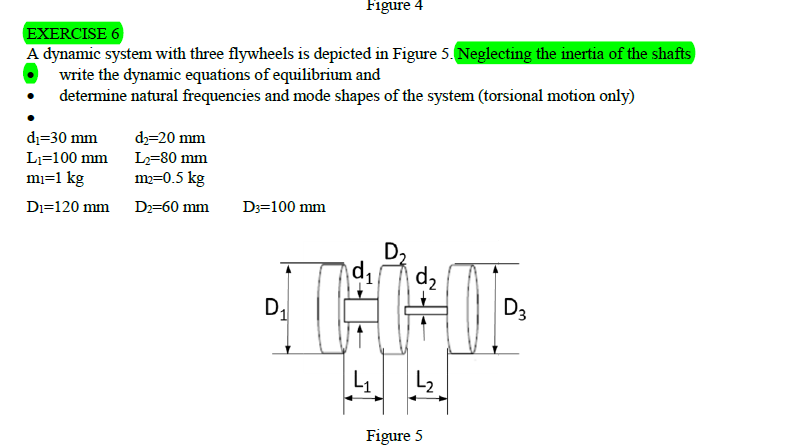

clear 
clc

G=7.7e10;

l1=.1;
l2=.08;

D1=0.12;
D2=.6;
D3=.1;

d1=0.03;
d2=0.02;

Jp1=pi()*D1^4/32;
Jp2=pi()*D2^4/32;
Jp3=pi()*D3^4/32;

Ip1=pi()*d1^4/32;
Ip2=pi()*d2^4/32;

k1=G*Ip1/l1;
k2=G*Ip2/l2;

M=[Jp1 0 0;
    0 Jp2 0;
    0 0  Jp3];
K=[k1 -k2 0;
    -k1 k2+k1 -k2;
    0 -k2 +k2];

%solve the eigenproblem det(K-w^2*M)=0, obtaining two values of w^2
[phi,w]=eig(K,M);

wn1=sqrt(w(1,1));
wn2=sqrt(w(2,2));
wn3=sqrt(w(3,3));

disp('1st torsional natural frequency [rad/s] = ')

1st torsional natural frequency [rad/s] = 


disp(wn1)

   5.4854e+04



disp(' ');

disp('2nd torsional natural frequency [rad/s] = ')

2nd torsional natural frequency [rad/s] = 


disp(wn2)

   1.9026e+03



disp(' ');

disp('3rd torsional natural frequency [rad/s] = ')

3rd torsional natural frequency [rad/s] = 


disp(wn3)

   3.9258e+04



disp(' ');


%put the value of wn1 (or wn2) in one of the two equations of the eigen
%problem to obtain phi1 (or phi2) and "normalize" it
phi1=phi(:,1)/max(abs(phi(:,1)));
phi2=phi(:,2)/max(abs(phi(:,2)));

disp('1st eigenvector = ')

1st eigenvector = 


disp(phi1)

    1.0000
   -0.0016
    0.0017



disp(' ');

disp('2nd eigenvector = ')

2nd eigenvector = 


disp(phi2)

    0.2466
    0.9976
    1.0000



disp(' ');